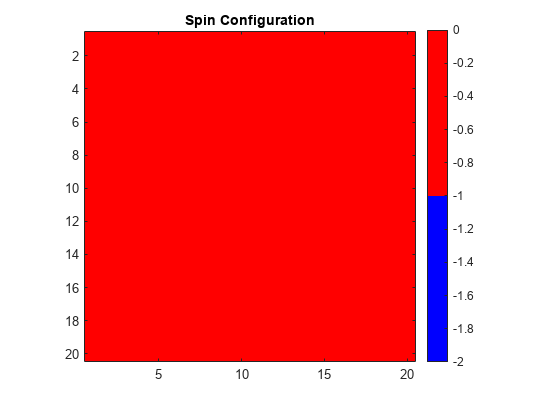

%% Ising Model Simulation using Metropolis Algorithm

% Parameters
N = 20; % Lattice size (20x20)
J = 5e-3; % Interaction strength (5 meV for ferromagnet)
k_B = 8.617333e-5; % Boltzmann constant in eV/K
mu = 1; % Magnetic moment (µ)
iterations = 4000; % Number of iterations for equilibration
T_initial = 50; % Initial temperature in Kelvin
post_iterations = 10000; % Number of iterations to calculate averages

% Initialize a 20x20 spin lattice with random +1/-1 values
spins = randi([0, 1], N, N) * 2 - 1; % Randomly assign -1 or +1 to spins

% Simulation for different temperatures
temperatures = 5:5:200; % Temperature range
energy_vals = zeros(size(temperatures)); % Array to store energies
magnetization_vals = zeros(size(temperatures)); % Array to store magnetizations

for t = 1:length(temperatures)
    T = temperatures(t);
    
    % Rerun the Metropolis algorithm for this temperature
    [energy, magnetization] = metropolis(spins, N, J, k_B, T, iterations, mu);
    
    % Calculate average energy and magnetization
    [avg_energy, avg_magnetization] = calculate_averages(spins, N, J, k_B, T, post_iterations, mu);
    
    % Store values in arrays
    energy_vals(t) = avg_energy;
    magnetization_vals(t) = avg_magnetization;
end


% Plot energy and magnetization as a function of temperature
figure;
subplot(2,1,1);
plot(temperatures, energy_vals, '-o');
title('Energy vs Temperature');
xlabel('Temperature (K)');
ylabel('Energy (meV)');

subplot(2,1,2);
plot(temperatures, magnetization_vals, '-o');
title('Magnetization vs Temperature');
xlabel('Temperature (K)');
ylabel('Magnetization');

% Repeat for Antiferromagnet (J = -5 meV)
J = -5e-3; % Switch to antiferromagnetic interaction strength

for t = 1:length(temperatures)
    T = temperatures(t);
    
    % Rerun the Metropolis algorithm for antiferromagnet
    [energy, magnetization] = metropolis(spins, N, J, k_B, T, iterations, mu);
    
    % Calculate average energy and magnetization
    [avg_energy, avg_magnetization] = calculate_averages(spins, N, J, k_B, T, post_iterations, mu);
    
    % Store values in arrays
    energy_vals(t) = avg_energy;
    magnetization_vals(t) = avg_magnetization;
end

% Plot energy and magnetization for antiferromagnet
figure;
subplot(2,1,1);
plot(temperatures, energy_vals, '-o');
title('Antiferromagnetic Energy vs Temperature');
xlabel('Temperature (K)');
ylabel('Energy (meV)');

subplot(2,1,2);
plot(temperatures, magnetization_vals, '-o');
title('Antiferromagnetic Magnetization vs Temperature');
xlabel('Temperature (K)');
ylabel('Magnetization');

%% Function Definitions

% Function to plot spin configuration

function plot_spins(spins)
    imagesc(spins); 
    colormap([0 0 1; 1 0 0]); % Blue for -1, Red for +1
    title('Spin Configuration');
    axis square;
    colorbar;
end

% Metropolis Algorithm Function
function [energy, magnetization] = metropolis(spins, N, J, k_B, T, iterations, mu)
    % Initialize energy and magnetization
    energy = -J * sum(sum(spins .* circshift(spins, [0, 1]) + spins .* circshift(spins, [1, 0])));
    magnetization = mu * sum(spins(:));

    for iter = 1:iterations
        for i = 1:N^2
            % Randomly select a spin
            row = randi([1, N]);
            col = randi([1, N]);
            
            % Calculate the change in energy ΔE
            neighbors_sum = spins(mod(row-2, N)+1, col) + spins(mod(row, N)+1, col) + ...
                            spins(row, mod(col-2, N)+1) + spins(row, mod(col, N)+1);
            dE = 2 * J * spins(row, col) * neighbors_sum;
            
            % Metropolis acceptance condition
            if dE < 0 || rand() < exp(-dE / (k_B * T))
                spins(row, col) = -spins(row, col);
                energy = energy + dE;
                magnetization = magnetization + 2 * mu * spins(row, col);
            end
        end
        
        % Plot the spin configuration periodically for visualization
        if mod(iter, 1000) == 0
            plot_spins(spins);
            pause(0.5); % Pause to allow for visualization
        end
    end
end

% Calculate Average Energy and Magnetization after Equilibration
function [avg_energy, avg_magnetization] = calculate_averages(spins, N, J, k_B, T, post_iterations, mu)
    energy = -J * sum(sum(spins .* circshift(spins, [0, 1]) + spins .* circshift(spins, [1, 0])));
    magnetization = mu * sum(spins(:));

    total_energy = 0;
    total_magnetization = 0;

    for iter = 1:post_iterations
        for i = 1:N^2
            row = randi([1, N]);
            col = randi([1, N]);

            neighbors_sum = spins(mod(row-2, N)+1, col) + spins(mod(row, N)+1, col) + ...
                            spins(row, mod(col-2, N)+1) + spins(row, mod(col, N)+1);
            dE = 2 * J * spins(row, col) * neighbors_sum;

            if dE < 0 || rand() < exp(-dE / (k_B * T))
                spins(row, col) = -spins(row, col);
                energy = energy + dE;
                magnetization = magnetization + 2 * mu * spins(row, col);
            end
        end
        
        total_energy = total_energy + energy;
        total_magnetization = total_magnetization + magnetization;
    end

    avg_energy = total_energy / post_iterations;
    avg_magnetization = total_magnetization / post_iterations;
end
